Test1 = zeros(Constants.AmountOfPhis, Constants.AmountOfOmegas);
Test2 = zeros(Constants.AmountOfPhis, Constants.AmountOfOmegas);
Test3 = zeros(Constants.AmountOfPhis, Constants.AmountOfOmegas, Constants.AmountOfPhis);

tic
for PhiIdx = 1 : Constants.AmountOfPhis
    for OmegaIdx = 1 : Constants.AmountOfOmegas
        Term1 = wDSHermitian(OmegaIdx, :, PhiIdx);
        Term2 = ReceivedFFT(:, OmegasFFTIndices(OmegaIdx));        
        
        Test1(PhiIdx, OmegaIdx) = sum(Term1);
        Test2(PhiIdx, OmegaIdx) = Term1 * Term2;
    end
end
toc

Elapsed time is 0.377388 seconds.



tic 
for OmegaIdx = 1 : Constants.AmountOfOmegas
    Term1 = ReceivedFFT(:, OmegasFFTIndices(OmegaIdx));
    for PhiIdx = 1 : Constants.AmountOfPhis
    Term2 = wDS(:, OmegaIdx, PhiIdx) .* 6;
        for PhiIdx1 = 1 : Constants.AmountOfPhis
            Term3 = wDSHermitian(OmegaIdx, :, PhiIdx1);
            
            LeftTerm = Term2;
            RightTerm = (Term3 .* norm(Term1));
            Test3(PhiIdx, OmegaIdx, PhiIdx1) = RightTerm * LeftTerm;
        end
    end
end
toc

Elapsed time is 64.636008 seconds.


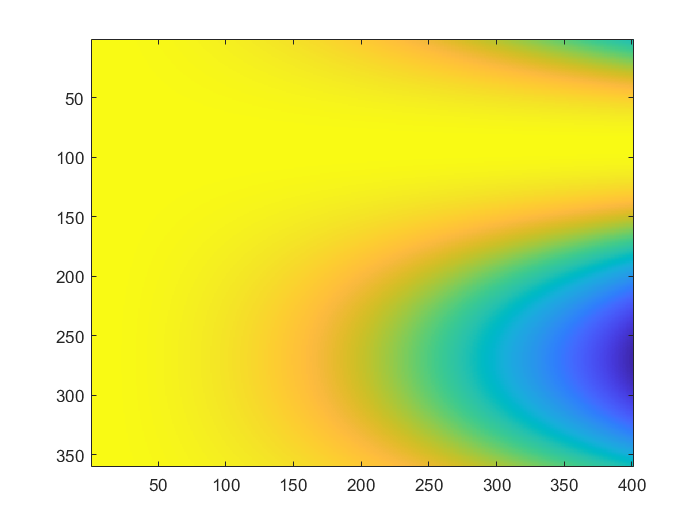


Test4 = zeros(Constants.AmountOfPhis, Constants.AmountOfOmegas);

for OmegaIdx = 1 : Constants.AmountOfOmegas
    Signal = ReceivedFFT(:, OmegasFFTIndices(OmegaIdx));
    BeamformerDirection = wDSHermitian(OmegaIdx, :, 90);
    for PhiIdx = 1 : Constants.AmountOfPhis
        Test4(PhiIdx, OmegaIdx) = BeamformerDirection * (wDS(:, OmegaIdx, PhiIdx) .* Constants.AmountOfMicrophones);
    end
end

imagesc(abs(Test4))

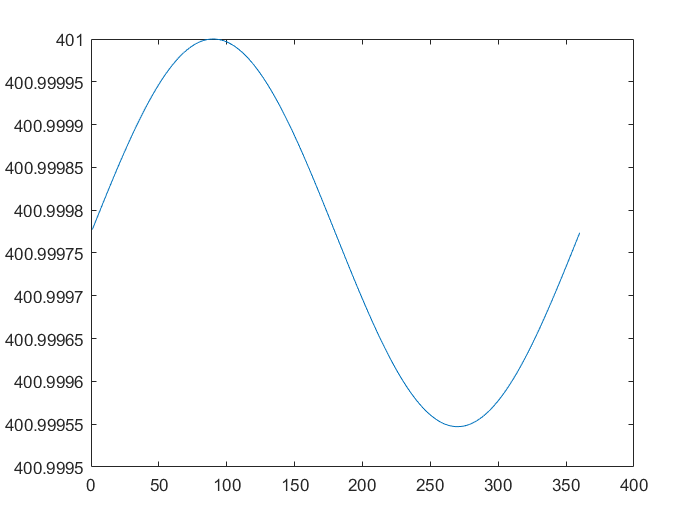

figure
plot(sum(abs(Test4), 2))

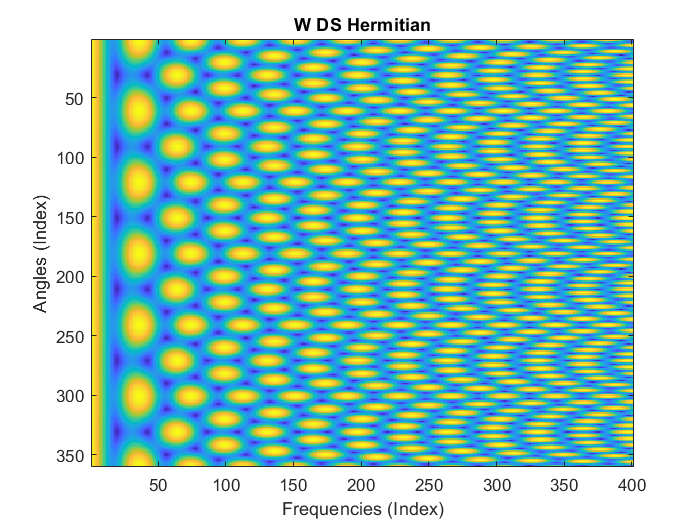

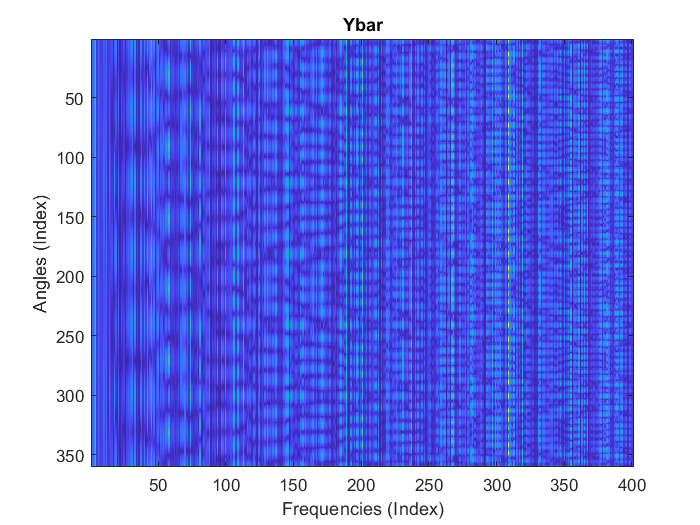

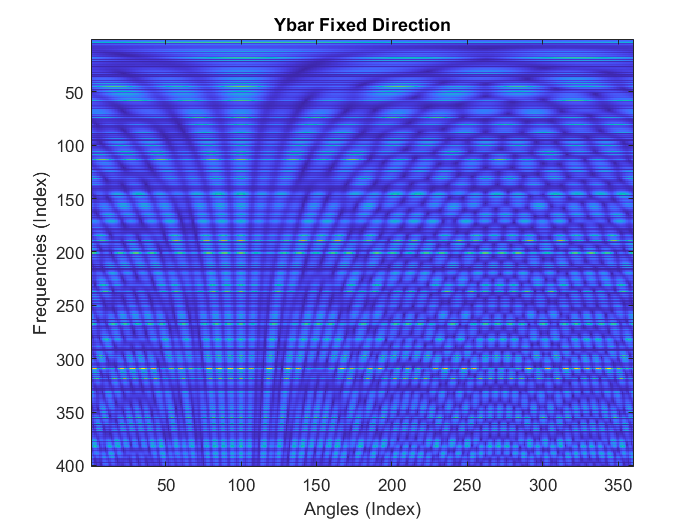

Error using waitforbuttonpress
waitforbuttonpress exit because target figure has been deleted

figure
imagesc(abs(Test1))
title("W DS Hermitian")
xlabel("Frequencies (Index)")
ylabel("Angles (Index)")

figure
imagesc(abs(Test2))
title("Ybar")
xlabel("Frequencies (Index)")
ylabel("Angles (Index)")

figure
imagesc(abs(squeeze(Test3(100, :, :))))
title("Ybar Fixed Direction")
xlabel("Angles (Index)")
ylabel("Frequencies (Index)")


figure
for Idx = 1 : Constants.AmountOfPhis
    imagesc(abs(squeeze(Test3(:, :, Idx))))
    title("Ybar : Fixed Looking Direction " + string(Idx))
    xlabel("Frequencies (Index)")
    ylabel("Angles (Index)")
    w = waitforbuttonpress;
end